## Bode Plot Design Question with: w0, w1, A, etc.


clc; clear all; close all; 

syms s w1 w2 w0 w
syms A Q
 


A= 100;
wp = 500;
wz =50;
%Q  =1.66% 1.66;

% Transfer Function:
n  = A*(1+s/wz);
d  = s*(1+s/wp);

a = 1/w;
a*100

$$ans = \frac{100}{w}$$

b = w/wz*a;
b*100

$$ans = 2$$

c = 1/(w/wp)*a*b;
c*100

$$ans = \frac{1000}{w^{2}}$$

D = expand(d);
q = solve(D);
T_s = simplifyFraction(n/d)

$$T\_s = \frac{1000\,\left(s+50\right)}{s\,\left(s+500\right)}$$

% convert from double to poly, if necessary. 
try
    a = sym2poly(n);
catch ME
    a = [n];
end
b = sym2poly(D)

b =     0.0020    1.0000         0


f = factor(D);
%generate the transfer function T    
T = tf(a,b)

T =
 
    2 s + 100
  -------------
  0.002 s^2 + s
 
Continuous-time transfer function.



[z,p,k]= zpkdata(T) %Cr 

z = 1×1 cell array
    {[-50]}


p = 1×1 cell array
    {2×1 double}


k = 1000

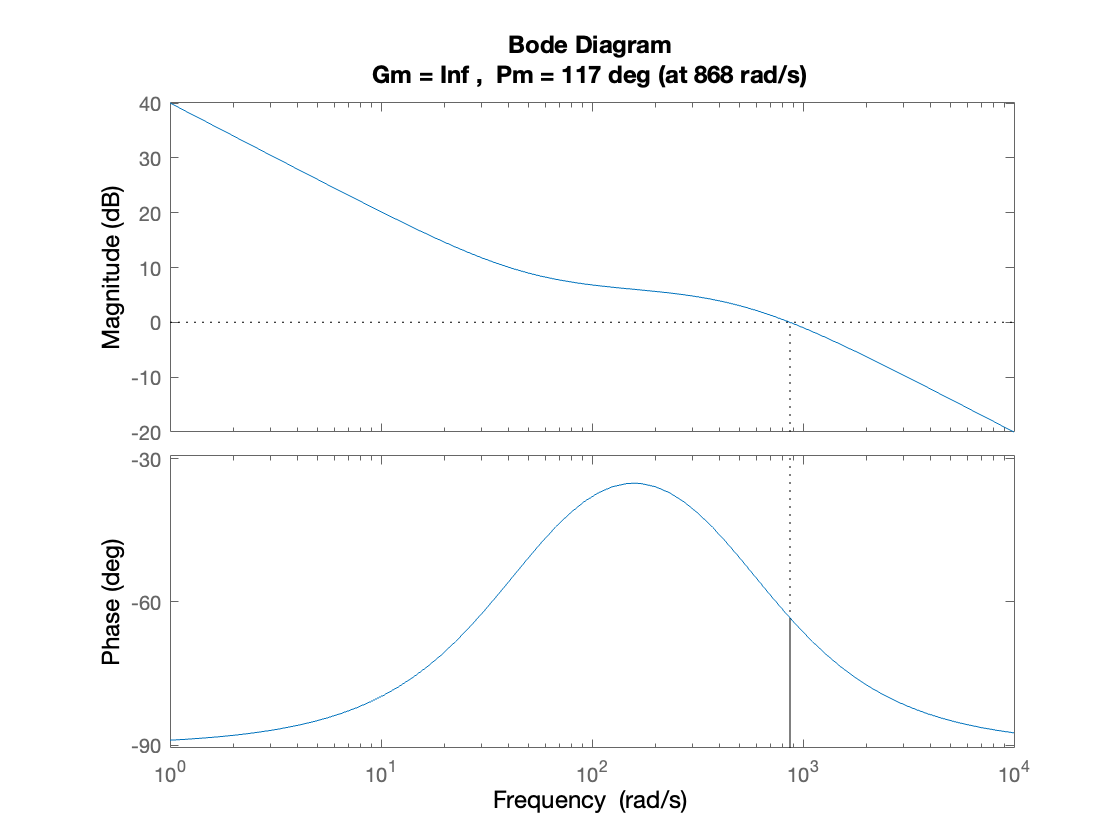

margin(T)


h = gcr;
%h.AxesGrid.Xunits ='Hz'
h.AxesGrid.TitleStyle.FontSize=12; 
h.AxesGrid.XLabelStyle.FontSize=12;
h.AxesGrid.YLabelStyle.FontSize=12;

fprintf('--------------------------------')

--------------------------------



%double(solve(10^(-1/(2*Q))*w0==2,w0))
%solve(-180==-180-45*log10(10w/w1),w))

# **TRANSIENT ANAYSIS**

## **System Type: 0,1,2 or >3(Lecture 16), Stability, K values**

clc; clear all; close all;
fprintf('***************************\n System Type \n ************************')

***************************
 System Type 
 ************************

syms s k
 

Gn = 1;% G or L          numerator
Gd = 1;% G or L          denominator
Hn = 1;% H =1 if NAN     numerator
Hd = 2;% H =1 if NAN     denominator

 G = Gn/Gd;
H = Hn/Hd;
% if H<=1
%     T_s = G
%     %fprintf('closed loop gain:' )
%     M = (1-(1/((1/T_s)+1)));
%     
%     % Compute simplified symbolic expression
%     Type = simplifyFraction(M,'Expand',true)
%     [num, den]=numden(M);
%     za = sym2poly(num);
%     type2=(num-za(end))/(den-za(end)); % is the number
%     [num1,den1]=numden(type2);
%     zb = sym2poly(num1);
%     zc = sym2poly(den1);
%     order = nnz(~zb);
%     t=0:1:10;
%     T=tf(zb,zc);
%     kp = limit(T_s,s,0); kpd=double(kp);
%     kv = limit(s*T_s,s,0);
%     ka = limit(s^2*T_s,s,0);
%     %A = max(step(T));
%     fprintf('************************* \n Step 1) Is it stable?')
%     routh(zc)
%     fprintf('************************* \n Step 2) If stable, this is a TYPE %2.0f SYSTEM',order)
%         if order ==0
%             fprintf('INPUT: output \n  Step: ess = %4.4f, kp = %4.4f  \n  Ramp: ess= ∞ \n Parab: ess = ∞', 1/(1+kp), kpd)
%         elseif order ==1
%             fprintf('INPUT: output \n  Step: ess = 0  \n  Ramp: ess= %4.4f ,kv = %4.4f \n Parab: ess = ∞, ka= %4.4f', 1/(kv),kv,ka)
%         elseif order ==2
%             fprintf('INPUT: output \n  Step: ess = 0  \n  Ramp: ess= 0 \n Parab: ess = %4.4f , ka = %4.4f', 1/(ka),ka)
%         else fprintf('Type 3 and up \n INPUT: \n  Step: ess = 0  \n  Ramp: ess= 0 \n Parab: ess=0')
%         end
%         kh=limit(H,s,0)
%         kp , kpd 
%         kv
%         ka
% elseif H~=1
    fprintf('closed loop gain:' )

closed loop gain:

    %H=1/(5*s+2)
    M = simplifyFraction((G/(1+G*H)))

Check for incorrect argument data type or missing argument in call to function 'simplifyFraction'.

    kh=limit(H,s,0);
    system = simplifyFraction(1-kh*M,'Expand',true);
    [num0,den0] = numden(M);
    num0p = sym2poly(num0);
    den0p = sym2poly(den0);
    za0 = sym2poly(num0); %convert to array
    type20=(num0-za0(end))/(den0-za0(end));
    [num0,den0]=numden(type20);
    zb0 = sym2poly(num0);
    order0 = nnz(~zb0);
    %A = max(step(tf(num0p,den0p)))
    fprintf('Step 1) Is it stable?')
    routh(den0p)
    fprintf('******* \n Step 2) If stable, this is a TYPE %2.0f SYSTEM',order0)
    kh
    a0 = den0p(end);
    b0 = num0p(end);
    a1 = den0p(end-1);
    try 
        b1 = num0p(end-1);
    catch ME
        b1 = 0;
    end
    a2 = den0p(end-2);
    try
        b2 = num0p(end-2);
    catch ME
        b2 = 0;
    end

        if order0 ==0
            fprintf('INPUT: \n  Step: ess = %4.4f, kh = %4.4f  \n  Ramp: ess = ∞ \n Parab: ess = ∞', 1/kh*((a0-b0*kh)/(a0)),kh)
        elseif order0 ==1
            fprintf('INPUT: \n  Step: ess = 0  \n  Ramp: ess= %4.4f ,kh = %4.4f \n Parab: ess = ∞',1/kh*((a1-b1*kh)/(a0)) ,kh)
        elseif order0 ==2 
            fprintf('INPUT: \n  Step: ess = 0  \n  Ramp: ess= 0 \n Parab: %4.4f , kh = %4.4f', 1/kh*((a2-b2*kh)/(a0)),kh)
        else fprintf('Type 3 and up \n INPUT: \n Step: ess = 0  \n Ramp: ess= 0 \n Parab: ess=0')
        end
        kh
%end

#### DAMPING

Damping of 1 is overdamped

clear n d;
[n,d] = numden(M)
Tx=sym2poly(M)
Ta=tf(Tx)
fprintf('Stability ********************************************************')
damp(Ta)

#### POLES AND ZEROS

%[r,p,k] = residue(a,b) % Partial fraction expansion
r(1)%/(s-p(1))+r(2)/(s-p(2))+r(3)/(s-p(3))+k)
pzplot(Ta,'r') 
step(Ta)
stepinfo(Ta)

#### BODE

margin(Ta)
h = gcr;
%h.AxesGrid.Xunits ='Hz'
h.AxesGrid.TitleStyle.FontSize=12; 
h.AxesGrid.XLabelStyle.FontSize=12;
h.AxesGrid.YLabelStyle.FontSize=12;
fprintf('-------------------------------------------------------------------------')

Stability comparison

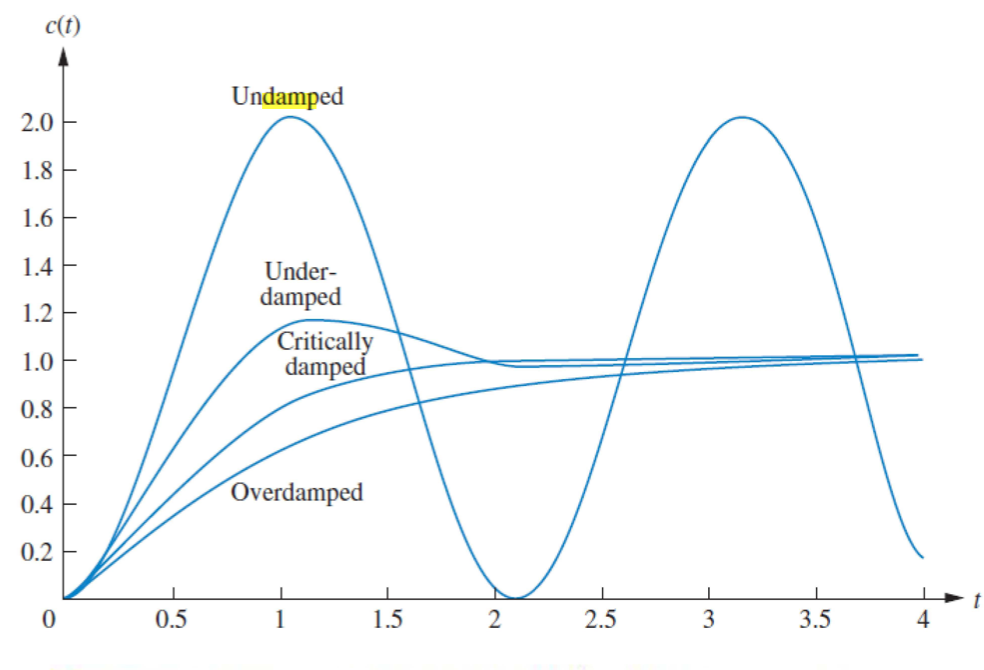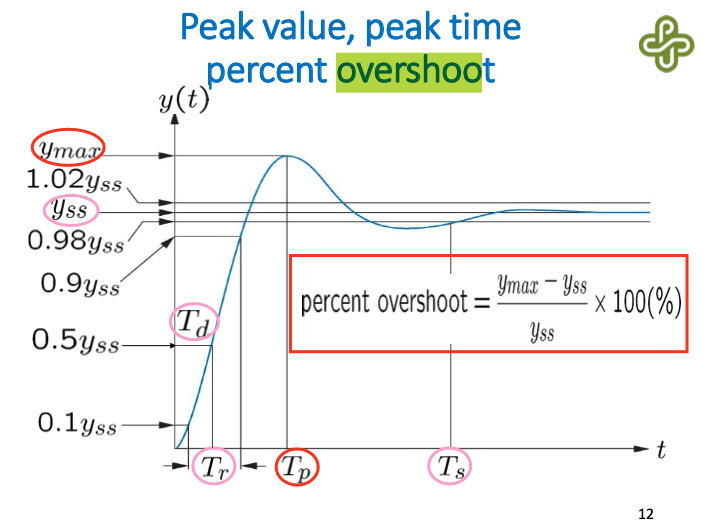

### PERCENT OVERSHOOT %OS

Y_max = .0833; % SettlingMin

Y_min = 1.3896e-6; % SettlingMax

OS = (Y_max-Y_min)/(Y_min)*100


### damping ratio &

b
w = sqrt( b(3))  %[NA dp w]
dp= (b(2))/(w*2)



## His Class Example

clear all; close all; clc;
s = tf('s')
G0 = 5;
w0 =1000;
G = G0/(1+s/w0);
Gc = 1'
Gc1 = Gc*G/(1+Gc*G);
step(Gc1);
k = 115.5;
Gc = k/s;
Gc1=G0*G/(1+Gc*G) 
% to get the sse 1 - Amplitude of Step 
stepinfo(Gc1)
stepDataOptions()



Routh Hurwitz Function

## Routh Hurwitz Function

function [x] = routh(x)

%% Routh-Hurwitz stability criterion
%
%  The Routh-Hurwitz stability criterion is a necessary (and frequently
%  sufficient) method to establish the stability of a single-input,
%  single-output(SISO), linear time invariant (LTI) control system.
%  More generally, given a polynomial, some calculations using only the
%  coefficients of that polynomial can lead us to the conclusion that it
%  is not stable.

%  Instructions
%  ------------
%
%  in this program you must give your system coefficients and the
%  Routh-Hurwitz table would be shown
%
%   Farzad Sagharchi ,Iran
%   2007/11/12

%% Initialization



% Taking coefficients vector and organizing the first two rows

coeffVector = x;
ceoffLength = length(x);
rhTableColumn = round(ceoffLength/2);

%  Initialize Routh-Hurwitz table with empty zero array
rhTable = zeros(ceoffLength,rhTableColumn);

%  Compute first row of the table
rhTable(1,:) = coeffVector(1,1:2:ceoffLength);

%  Check if length of coefficients vector is even or odd
if (rem(ceoffLength,2) ~= 0)
    % if odd, second row of table will be
    rhTable(2,1:rhTableColumn - 1) = coeffVector(1,2:2:ceoffLength);
else
    % if even, second row of table will be
    rhTable(2,:) = coeffVector(1,2:2:ceoffLength);
end

%% Calculate Routh-Hurwitz table's rows

%  Set epss as a small value
epss = 0.01;

%  Calculate other elements of the table
for i = 3:ceoffLength
   
    %  special case: row of all zeros
    if rhTable(i-1,:) == 0
        order = (ceoffLength - i);
        cnt1 = 0;
        cnt2 = 1;
        for j = 1:rhTableColumn - 1
            rhTable(i-1,j) = (order - cnt1) * rhTable(i-2,cnt2);
            cnt2 = cnt2 + 1;
            cnt1 = cnt1 + 2;
        end
    end
    
    for j = 1:rhTableColumn - 1
        %  first element of upper row
        firstElemUpperRow = rhTable(i-1,1);
        
        %  compute each element of the table
        rhTable(i,j) = ((rhTable(i-1,1) * rhTable(i-2,j+1)) - ....
            (rhTable(i-2,1) * rhTable(i-1,j+1))) / firstElemUpperRow;
    end
    
    
    %  special case: zero in the first column
    if rhTable(i,1) == 0
        rhTable(i,1) = epss;
    end
end

%%  Compute number of right hand side poles(unstable poles)
%   Initialize unstable poles with zero
unstablePoles = 0;

%   Check change in signs
for i = 1:ceoffLength - 1
    if sign(rhTable(i,1)) * sign(rhTable(i+1,1)) == -1
        unstablePoles = unstablePoles + 1;
    end
end

%   Print calculated data on screen
fprintf('\n Routh-Hurwitz Table:\n')
rhTable

%   Print the stability result on screen
if unstablePoles == 0
    fprintf('~~~~~> STABLE system <~~~~~\n')
else
    fprintf('~~~~~> UNSTABLE system <~~~~~\n')
end

fprintf('\n Number of right hand side poles =%2.0f\n',unstablePoles)


    sysRoots = roots(coeffVector);
    fprintf('\n Given polynomial coefficients roots: \n')
    sysRoots
end